data = readtable('debica.csv');
data = data((end-999):end,["Data"; "Zamkniecie"])

data = 1000×2 table
       Data       Zamkniecie
    __________    __________

    2019-03-13      70.733  
    2019-03-14      71.889  
    2019-03-15      71.724  
    2019-03-18       72.88  
    2019-03-19      71.889  
    2019-03-20      72.384  
    2019-03-21      71.393  
    2019-03-22      71.393  
    2019-03-25      71.063  
    2019-03-26      69.576  
    2019-03-27      69.245  
    2019-03-28      70.402  
    2019-03-29      70.402  
    2019-04-01       69.74  
    2019-04-02      70.237  
    2019-04-03      69.576  


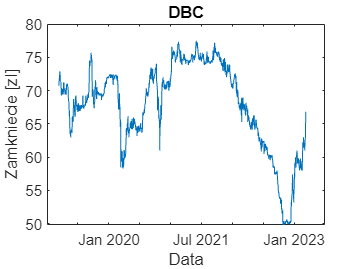

plot(data, "Data", "Zamkniecie")
ylabel("Zamkniecie [zl]")
title("DBC")

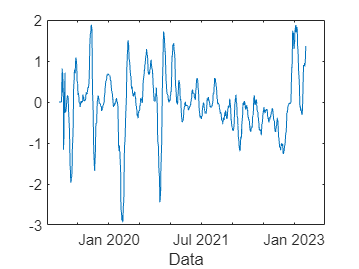

EMA12 = zeros(1,1000);
EMA26 = zeros(1,1000);
MACD = zeros(1,1000);

for i = 1:1000
    EMA26(i) = EMA(26,data,i,"Zamkniecie");
    EMA12(i) = EMA(12,data,i,"Zamkniecie");
    MACD(i) = EMA12(i) - EMA26(i);
end
plot(data.Data, MACD, "DisplayName", "MACD");
xlabel("Data")
hold on;

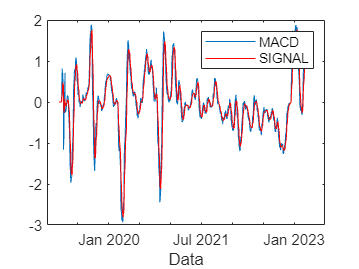

MACD = transpose(MACD);
MACD=array2table(MACD);
SIGNAL=zeros(1,1000);
for i = 1:1000
    SIGNAL(i) = EMA(9,MACD,i,1);
end
plot(data.Data, SIGNAL, "r", "DisplayName", "SIGNAL" )
legend();

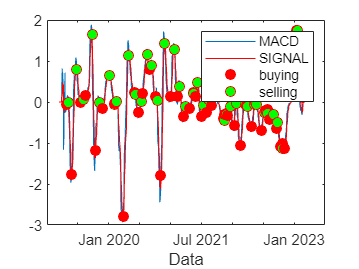

konto = 1000.00;
posiadaneAkcje = 0;
MACD = table2array(MACD);
for i = 28:1000
    if(MACD(i)>=SIGNAL(i) && MACD(i-1)<SIGNAL(i-1))%kupno
        posiadaneAkcje = posiadaneAkcje + floor(konto/data{i,"Zamkniecie"});
        konto = konto - floor(konto/data{i,"Zamkniecie"}) * data{i,"Zamkniecie"};
        plot(data{i,"Data"},MACD(i),'or','MarkerFaceColor','r', "HandleVisibility","off")
    elseif(MACD(i)<=SIGNAL(i) && MACD(i-1)>SIGNAL(i-1))%sprzedaz
        konto = konto + posiadaneAkcje * data{i,"Zamkniecie"};
        posiadaneAkcje = 0;
        plot(data{i,"Data"},MACD(i),'or','MarkerFaceColor','g', "HandleVisibility","off")
    end
end
plot(nan, nan, 'or','MarkerFaceColor', 'r', "DisplayName", "buying");
plot(nan, nan, 'or','MarkerFaceColor', 'g', "DisplayName", "selling");

konto=konto+posiadaneAkcje*data{1000,"Zamkniecie"}

konto = 1.0175e+03

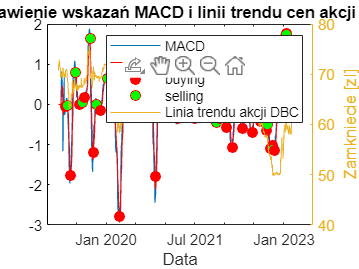

%dodatkowa sekcja służąca do porównania cen zamknięcia wzgledem wybranych
%przez MACD momentów kupna/sprzedaży
yyaxis right
ylabel("Zamkniecie [zl]")
plot(data.Data, data.Zamkniecie,"Color", "#EDB224", "DisplayName","Linia trendu akcji DBC");
title("Zestawienie wskazań MACD i linii trendu cen akcji DBC")
hold off

function ema = EMA(N, dataTable ,dataIndex, dataColumn)
    if(dataIndex<=N)
        ema = dataTable{dataIndex,dataColumn};
    else
        alpha = 2/(N + 1);
        power = 0;
        bottom = 0;
        top = 0;
        for j=dataIndex:-1:dataIndex-N
            top=top+(1-alpha)^(power)*dataTable{j, dataColumn};
            bottom = bottom + (1-alpha)^(power);
            power=power+1;
        end
        ema = top/bottom;
    end
end